clc
close all
warning off

% Loading the dataset with labels
dataset = imageDatastore('DATASET','IncludeSubfolders',true, 'LabelSource','foldernames'); 

% Dividing the dataset into training and validation dataset
[Training_dataset, Validation_dataset] = splitEachLabel(dataset, 7.0);

% Findin out the number of classes
Number_of_Classes = numel(categories(Training_dataset.Labels));

# Calling AlexNet Model and configuring the feature learner layer

net = alexnet;
analyzeNetwork(net);

Input_Layer_Size = net.Layers(1).InputSize; % Getting input size of alexnet

Layer_Graph = layerGraph(net);

Feature_Learner = net.Layers(23);
Output_Classifier = net.Layers(25);

New_Feature_Learner = fullyConnectedLayer(Number_of_Classes, ...
                            'Name', 'Facial Feature Learner', ...
                            'WeightLearnRateFactor', 10, ...
                            'BiasLearnRateFactor', 10);
New_Classifier_Layer = classificationLayer('Name', 'Face Classifier');
Layer_Graph = replaceLayer(Layer_Graph, Feature_Learner.Name, New_Feature_Learner);
Layer_Graph = replaceLayer(Layer_Graph, Output_Classifier.Name, New_Classifier_Layer);
analyzeNetwork(Layer_Graph)

# Data Augmentation



Pixel_Range = [-30 30];
Scale_Range = [0.9, 1.1];

Image_Augmenter = imageDataAugmenter( ...
                    'RandXReflection',true, ...
                    'RandXTranslation',Pixel_Range, ...
                    'RandYTranslation',Pixel_Range, ...
                    'RandXScale',Scale_Range, ...
                    'RandYScale',Scale_Range);

Augmented_Training_Image = augmentedImageDatastore(Input_Layer_Size(1:2), Training_dataset, ...
                                'DataAugmentation',Image_Augmenter);
Augmented_Validation_Image = augmentedImageDatastore(Input_Layer_Size(1:2), Validation_dataset);


# Hyperparameter Tuning

Size_of_Minibatch = 32;
Validation_Frequency = 2;
% floor(numel(Training_dataset.Files)/Size_of_Minibatch);
Training_Options = trainingOptions('sgdm', ... 
                    'MiniBatchSize',Size_of_Minibatch, ...
                    'MaxEpochs', 30, ...
                    'InitialLearnRate',0.0003, ...
                    'Shuffle', 'every-epoch', ...
                    'ValidationFrequency',Validation_Frequency, ...
                    'ValidationData',Augmented_Validation_Image, ...
                    'verbose',false, ...
                    'Plots','training-progress');


# Training the Model

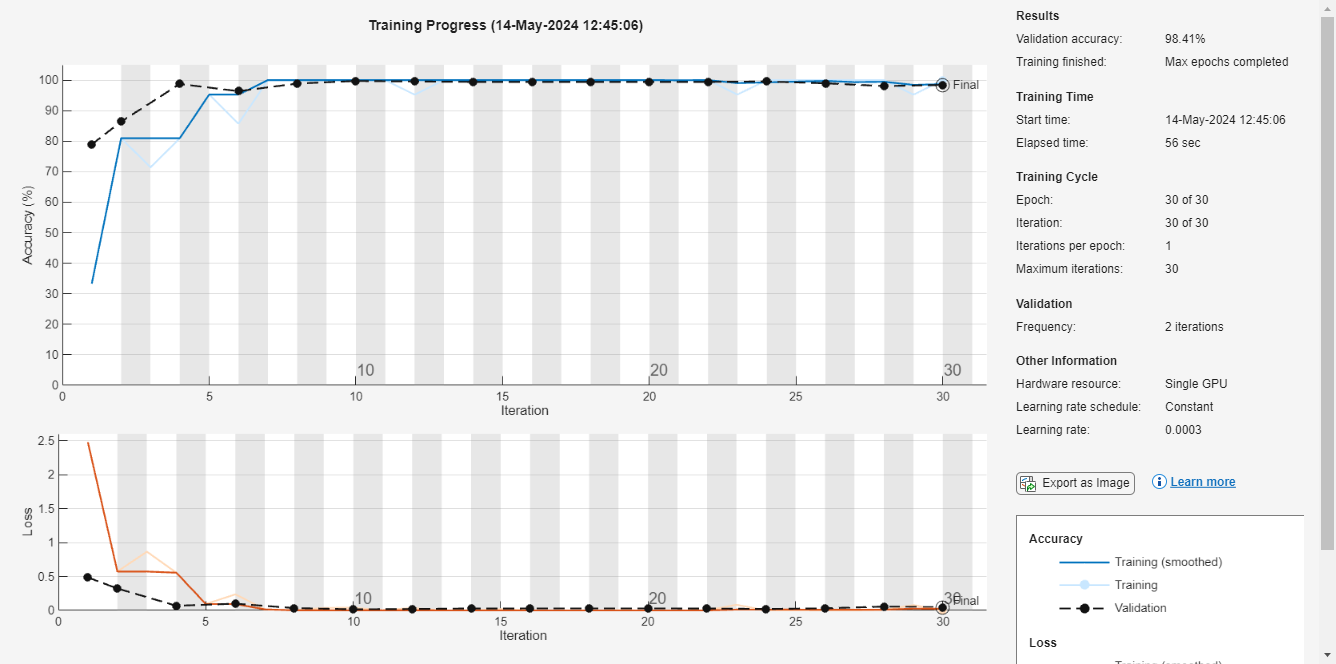

net = trainNetwork(Augmented_Training_Image, Layer_Graph, Training_Options);

save net;